## Verification

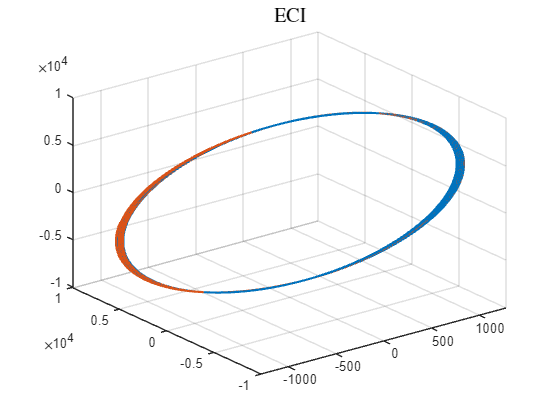

veri = importdata("dm_output.dat");
ECI = importdata("ECI.txt");

vECI_x = veri(:,9)/1000;
vECI_y = veri(:,10)/1000;
vECI_z = veri(:,11)/1000;

figure;
plot3(vECI_x, vECI_y, vECI_z,'LineWidth',1.5);
grid on;
hold on;
plot3(ECI(:,2), ECI(:,3), ECI(:,4),'LineWidth',1.5);
hold off
title('ECI','FontSize', 15,"interpreter","latex");

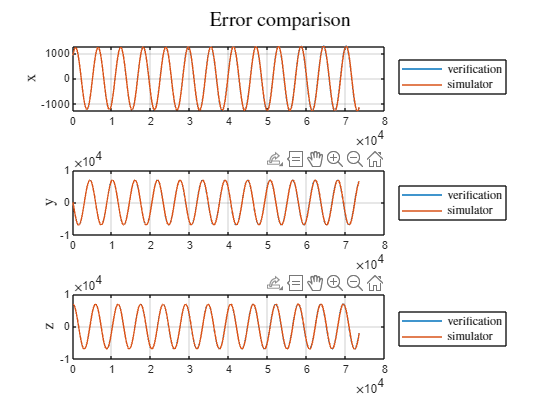




subplot(3, 1, 1);
plot(veri(:,1), vECI_x);
hold on 
grid on
plot(ECI(:,1),ECI(:,2))
hold off
ylabel("x","FontSize",12,"Interpreter","latex")
legend("verification","simulator","interpreter","latex","Location","eastoutside")

subplot(3, 1, 2);
plot(veri(:,1), vECI_y);
hold on 
grid on
plot(ECI(:,1),ECI(:,3));
hold off
ylabel("y","FontSize",12,"Interpreter","latex")
legend("verification","simulator","interpreter","latex","Location","eastoutside")

subplot(3, 1, 3);
plot(veri(:,1), vECI_z);
hold on 
grid on
plot(ECI(:,1),ECI(:,4));
hold off
ylabel("z","FontSize",12,"Interpreter","latex")
legend("verification","simulator","interpreter","latex","Location","eastoutside")

sgtitle("Error comparison",'FontSize', 15,"interpreter","latex");

## ECI

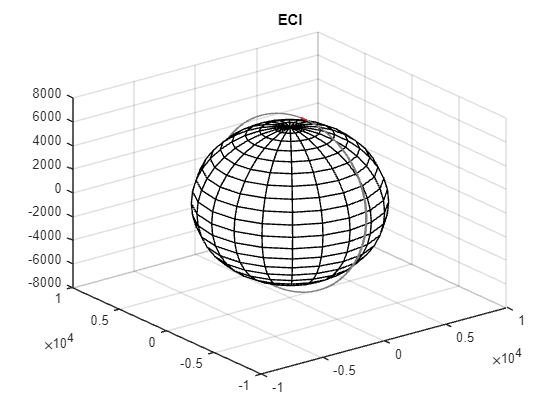

ECI = importdata("ECI.txt");

figure

plot3(ECI(:,2), ECI(:,3), ECI(:,4),'LineStyle','--','LineWidth',0.5,'color',[.5 .5 .5])
hold on

% Initialize the plot
h = plot3(ECI(1, 2), ECI(1, 3), ECI(1, 4),'LineWidth',1.5,'color','r');
grid on;
title('ECI');
hold on
xlim([-1e4 1e4]);
ylim([-1e4 1e4]);
zlim([-8e3 8e3]);

% Make unit sphere
[x1,y1,z1] = sphere;
% Scale to desire radius.
radius = 6378;
x2 = x1 * radius;
y2 = y1 * radius;
z2 = z1 * radius;

% Plot as surface.
surf(x2, y2, z2, 'FaceColor', [1, 1, 1], 'EdgeColor', [0, 0, 0]);

% Run for simulation
for i = 2:length(ECI(:, 1))
    % Update the plot data
    set(h, 'XData', ECI(1:i, 2), 'YData', ECI(1:i, 3), 'ZData', ECI(1:i, 4));

    % Pause for a short duration to control animation speed
    pause(0.01); % Adjust the pause duration as needed
end

## ECEF

ECEF = importdata("ECEF.txt");

figure

plot3(ECEF(:,1), ECEF(:,2), ECEF(:,3),'LineStyle','--','LineWidth',0.5,'color',[.5 .5 .5])
hold on

% Initialize the plot
h = plot3(ECEF(1, 1), ECEF(1, 2), ECEF(1, 3),'LineWidth',1.5,'color','r');
grid on;
title('ECEF');
hold on

% Make unit sphere
[x1,y1,z1] = sphere;
% Scale to desire radius.
radius = 6378;
x2 = x1 * radius;
y2 = y1 * radius;
z2 = z1 * radius;

xlim([-1e4 1e4]);
ylim([-1e4 1e4]);
zlim([-8e3 8e3]);

% Plot as surface.
earth = surf(x2,y2,z2);

set(earth, 'FaceColor', [1 1 1],'EdgeColor',[0 0 0]);

% Run for simulation
for i = 2:length(ECEF(:, 1))
    % Update the plot data
    set(h, 'XData', ECEF(1:i, 1), 'YData', ECEF(1:i, 2), 'ZData', ECEF(1:i, 3));

    % Pause for a short duration to control animation speed
    pause(0.01); % Adjust the pause duration as needed
end



## Groundtrack

GEO = importdata("GEO.txt");
figure
% for i = 2:length(GEO(:, 1))
%     % Update the plot data
%     ground_track(GEO(1:i,2), GEO(1:i,1));
% 
%     % Pause for a short duration to control animation speed
%     pause(0.01); % Adjust the pause duration as needed
% end

ground_track(GEO(:,2),GEO(:,1))

% lla = ecef2lla([ECEF(:,1)*1000 ECEF(:,2)*1000 ECEF(:,3)*1000], 'WGS84');
% geoscatter(lla(:,1), lla(:,2))


## quaternions

Q = importdata("q.txt");

% figure
% plot(Q(:,1),rad2deg(Q(:,2)),'LineWidth',1.5)
% hold on 
% plot(Q(:,1),rad2deg(Q(:,3)),'LineWidth',1.5)
% plot(Q(:,1),rad2deg(Q(:,4)),'LineWidth',1.5)
% hold off
% grid on 
% xlim([0 800])
% xlabel("Time","FontSize",12,"Interpreter","latex")
% legend("pitch", "roll", "yaw")
% title("Euler","FontSize",15,"Interpreter","latex")

figure
plot(Q(:,1),Q(:,2),'LineWidth',1.5)
hold on 
plot(Q(:,1),Q(:,3),'LineWidth',1.5)
plot(Q(:,1),Q(:,4),'LineWidth',1.5)
plot(Q(:,1),Q(:,5),'LineWidth',1.5)
hold off
grid on 
legend("$q_w$", "$q_x$", "$q_y$", "$q_z$","interpreter","latex","Location","best")



wrapped_phase_data = [Q(:,1), Q(:,4)];

% Unwrap the phase column (assuming 'y' is in the second column)
wrapped_y = wrapped_phase_data(:, 2);
unwrapped_y = unwrap(wrapped_y);

% Plot the wrapped and unwrapped phase data
figure;
subplot(2, 1, 1);
plot(wrapped_phase_data(:, 1), wrapped_phase_data(:, 2), 'b', 'LineWidth', 2);
title('Wrapped Phase Data');

subplot(2, 1, 2);
plot(wrapped_phase_data(:, 1), unwrapped_y, 'r', 'LineWidth', 2);
title('Unwrapped Phase Data');
xlabel('Time');
ylabel('Phase');




figure
subplot(2, 2, 1);
plot(Q(:,1),Q(:,2),'LineWidth',1.5)
title("$q_w$","FontSize",15,"Interpreter","latex")
xlabel("Time","FontSize",12,"Interpreter","latex")
xlim([0 800])
grid on 

subplot(2, 2, 2);
plot(Q(:,1),Q(:,3),'LineWidth',1.5)
title("$q_x$","FontSize",15,"Interpreter","latex")
xlabel("Time","FontSize",12,"Interpreter","latex")
xlim([0 800])
grid on 

subplot(2, 2, 3);
plot(Q(:,1),Q(:,4),'LineWidth',1.5)
title("$q_y$","FontSize",15,"Interpreter","latex")
xlabel("Time","FontSize",12,"Interpreter","latex")
xlim([0 800])
grid on 

subplot(2, 2, 4);
plot(Q(:,1),Q(:,5),'LineWidth',1.5)
title("$q_z$","FontSize",15,"Interpreter","latex")
xlabel("Time","FontSize",12,"Interpreter","latex")
xlim([0 800])
ylim([-1 1.2])
grid on 

